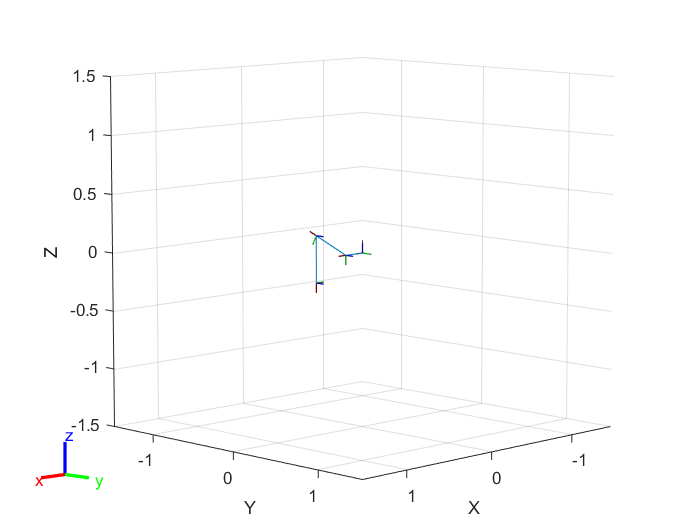

ans =   Axes (Primary) with properties:

             XLim: [-1.5000 1.5000]
             YLim: [-1.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


%%% LEG MODEL FOR RIGHT LEGS
%% Multibody ee frame = Rst ee frame
% X = z
% Y = y
% Z = -x
%% 90 degrees rotated acw from y-axis in rst

robot = rigidBodyTree;

dhparams = [0 0 0 0;
      l1 -pi/2 0 0;
      l2 0 0 0;
      l3_orig 0 0 0];
  
body1 = rigidBody('body1');
jnt1 = rigidBodyJoint('jnt1','revolute');
body2 = rigidBody('body2');
jnt2 = rigidBodyJoint('jnt2','revolute');
body3 = rigidBody('body3');
jnt3 = rigidBodyJoint('jnt3','revolute');
body4 = rigidBody('body4');
jnt4 = rigidBodyJoint('jnt4','revolute');

%Home Config
jnt2.HomePosition = 0;
jnt3.HomePosition = -pi/6;
jnt4.HomePosition = 2*pi/3;

%Joint Limits
jnt2.PositionLimits = [-pi,pi];
jnt3.PositionLimits = [-pi,pi];
jnt4.PositionLimits = [-pi,pi];

setFixedTransform(jnt1,dhparams(1,:),'dh');
setFixedTransform(jnt2,dhparams(2,:),'dh');
setFixedTransform(jnt3,dhparams(3,:),'dh');
setFixedTransform(jnt4,dhparams(4,:),'dh');

body1.Joint = jnt1;
body2.Joint = jnt2;
body3.Joint = jnt3;
body4.Joint = jnt4;

addBody(robot,body1,'base')
addBody(robot,body2,'body1')
addBody(robot,body3,'body2')
addBody(robot,body4,'body3')

show(robot)